# **Lab 1 - Model fitting**

# Submitted by: Priyanshu Rawat

#### Question 1-

In the question, we're given with 5 data points. Assuming the equation of the 2-D line model to be `y = a1*x + a2`, where `a1` & ``a2`` are the linear unknowns. 

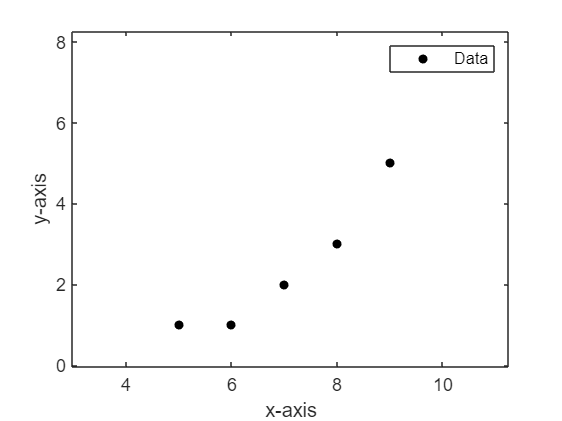

% Storing given raw data points
data_points = [5,1; 6,1; 7,2; 8,3; 9,5];

% Plotting the raw data points 
figure;
plot(data_points(:,1), data_points(:,2), '.black', 'MarkerSize',15);
% title('Raw data points');
ylabel('y-axis');
xlabel('x-axis');
legend('Data');
xlim([0 10]);
ylim([0 10]);
xlim([2.99 11.25])
ylim([-0.02 8.25])

% Number of given data points is 5
N = 5;

% Number of basis function is 2 for the assumed 2-D line model
M = 2;

% Matrix A of order N X M
A = [5 1; 6 1; 7 1; 8 1; 9 1];

% Matrix B of order N x 1
B = [1; 1; 2; 3; 5];

% Solving the linear unknowns
X = inv(transpose(A)*A)*transpose(A)*B;

% Linear unkowns
a1 = X(1,1)

a1 = 1.0000

a2 = X(2,1)

a2 = -4.6000

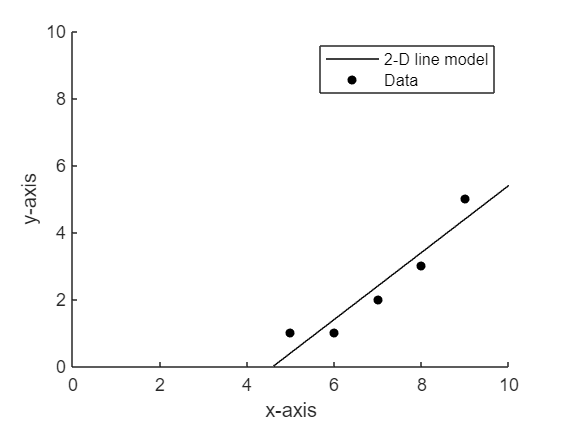

% Plotting the 2-D line model and the data point
x = 4:0.5:10;
y = a1*x + a2;
figure;
hold on;
plot(x,y, 'black');
plot(data_points(:,1), data_points(:,2), '.black', 'MarkerSize',15);
% title('Raw data points with 2-D line model');
ylabel('y-axis');
xlabel('x-axis');
legend('2-D line model', 'Data');
xlim([0 10]);
ylim([0 10]);
hold off;

#### Question 2-

Adding the (8,14) data point to the list of raw data points which gives a total of 6 data points. Again, assuming the equation of the 2-D line model to be `y = a1*x + a2`, where `a1` & ``a2`` are the linear unknowns. 

The new data point (8,14) is an outlier of the set, thus the model obtained by solving normal equation is shifted away from other points towards this new data point leading to a misleading model. This is mainly because the outlier (8,14) has a larger residual value compared to other data points within the set which is then augmented when calculating the sum of the squares. 

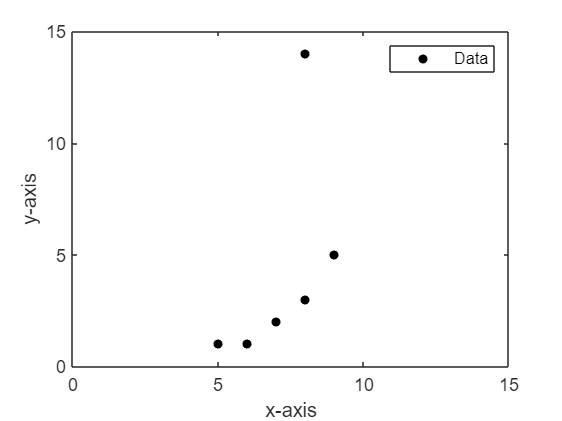

% Given data points inlcuding (8,14)
data_points_new = [5,1; 6,1; 7,2; 8,3; 9,5; 8,14];

% Plotting the raw data points 
figure;
plot(data_points_new(:,1), data_points_new(:,2), '.black', 'MarkerSize',15)
% title('New raw data points');
ylabel('y-axis')
xlabel('x-axis')
legend('Data')
xlim([0 15]);
ylim([0 15]);


% Number of given data points is 6
N_new = 6;

% Number of basis function is 2 for the assumed 2-D line model
M_new = 2;

% Matrix A of order N X M
A_new = [5 1; 6 1; 7 1; 8 1; 9 1; 8,1];

% Matrix B of order N x 1
B_new = [1; 1; 2; 3; 5; 14];

% Solving the linear unknowns
X_new = inv(transpose(A_new)*A_new)*transpose(A_new)*B_new;

% Linear unkowns
a1_new = X_new(1,1)

a1_new = 1.8154

a2_new = X_new(2,1)

a2_new = -8.6769

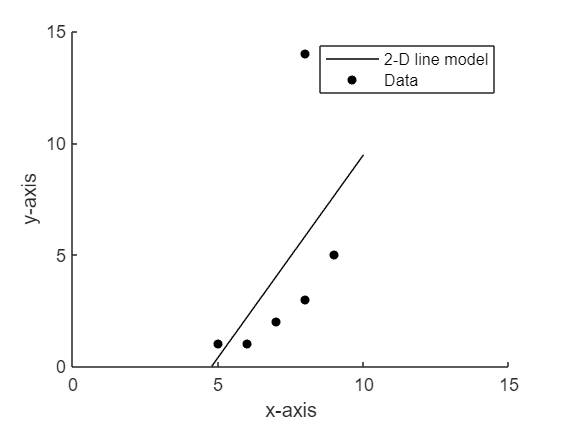

% Plotting the 2-D line model and the data point
x_new = 4:0.5:10;
y_new = a1_new*x_new + a2_new;
figure;
hold on;
plot(x_new,y_new, 'black');
plot(data_points_new(:,1), data_points_new(:,2),  '.black', 'MarkerSize',15);
% title('New raw data points with 2-D line model');
ylabel('y-axis');
xlabel('x-axis');
legend('2-D line model', 'Data', 'Location','northeast');
xlim([0 15]);
ylim([0 15]);
hold off

#### Question 3-

Loading the data file and plotting the required data. 

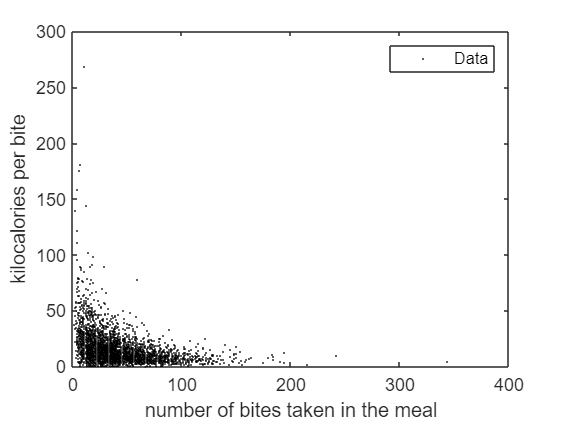

% Loading the data from text file
filename = '83people-all-meals.txt';
delimiterIn = ' ';
data = importdata(filename,delimiterIn);

% Saving data in variables
participant_id = data(:,1);
meal_id = data(:,2);
num_bites_in_meal = data(:,3);
num_kcal_consumed = data(:,4);

% Estimating kilocalories consumed per bite (dividend of the fourth and third column)
kcal_per_bite = rdivide(num_kcal_consumed, num_bites_in_meal);

% Plotting the data
plot(num_bites_in_meal, kcal_per_bite, '.black', 'MarkerSize',2);
% title('Plot of the required data');
xlabel('number of bites taken in the meal');
ylabel('kilocalories per bite');
legend('Data');

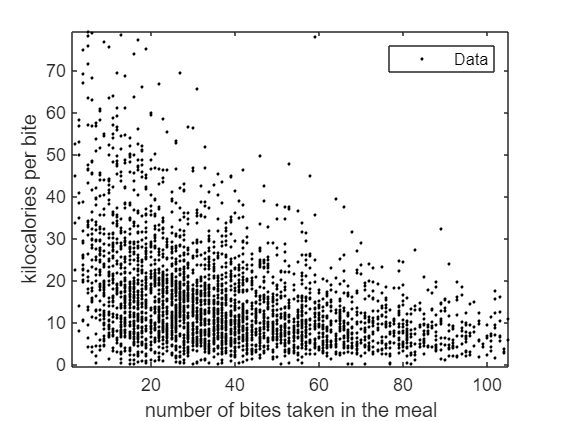


plot(num_bites_in_meal, kcal_per_bite, '.black', 'MarkerSize',5);
% title('Zoomed plot of the required data');
xlabel('number of bites taken in the meal');
ylabel('kilocalories per bite');
legend('Data');
xlim([1.4 105.1])
ylim([-0.4 79.2])

Model-1: Fitting a non-linear quadratic model with equation `y = a1*x^2 + a2*x + a3`

% Number of given data points is 3398
N = 3398;

% Number of basis function is 3
M = 3;

% y = a1*x2 + a2*x + a3
x1 = power(kcal_per_bite,2);
x2 = power(kcal_per_bite,1);

% Matrix A of order N X M
A = [x1, x2, ones(N,1)];

% Matrix B of order N x 1
B = num_bites_in_meal;

% Solving the linear unknowns
X = inv(transpose(A)*A)*transpose(A)*B;

% Linear unkowns
a1 = X(1,1)

a1 = 0.0047

a2 = X(2,1)

a2 = -1.1417

a3 = X(3,1)

a3 = 57.6343

y = a1*(20^2) + a2*(20) + a3

y = 36.6688

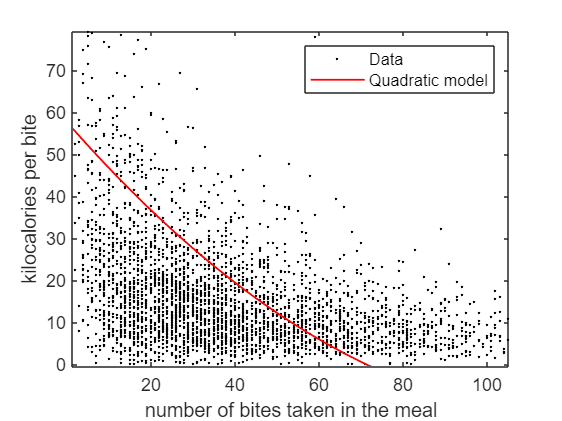

% Plotting the 2-D line model and the data point
x = 0:1:250;
y = a1*power(x,2) + a2*power(x,1) + a3;

plot(num_bites_in_meal, kcal_per_bite, '.black', 'MarkerSize',4);
xlim([1.4 105.1])
ylim([-0.4 79.2])
hold on;
plot(x,y, Color='red', LineWidth=1);
legend('Data', 'Quadratic model', 'Location','northeast');
% title('Fitting a quadratic model');
xlabel('number of bites taken in the meal');
ylabel('kilocalories per bite');
hold off;


% Evaluating the model fit by calculating the residual squared
residual = sum(num_bites_in_meal) - (sum(a1*power(kcal_per_bite,2) + a2*power(kcal_per_bite,1) + a3));
residualsquared_quad = residual^2

residualsquared_quad = 7.6233e-21

Model-2: Fitting a non-linear quadratic rational model with equation `y = a1*(x/(x^2-1))`

% Number of given data points is 3398
N = 3398;

% Number of basis function is 1
M = 1;

% Matrix A of order N X M
A = kcal_per_bite./(kcal_per_bite.^2-1);

% Matrix B of order N x 1
B = num_bites_in_meal;

% Solving the linear unknowns
X = inv(transpose(A)*A)*transpose(A)*B;

% Linear unkowns
a1 = X

a1 = 0.4496

y = a1*(20/((20^2)-1))

y = 0.0225

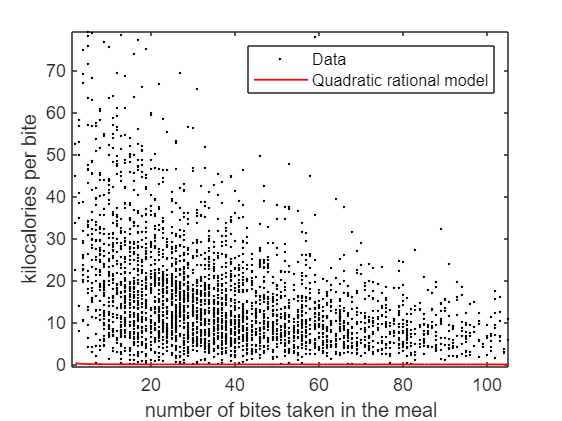

% Plotting the 2-D line model and the data point
x = 0:1:250;
y = a1*(x./(x.^2-1));
plot(num_bites_in_meal, kcal_per_bite, '.black', 'MarkerSize',4);
xlim([1.4 105.1])
ylim([-0.4 79.2])
hold on;
plot(x,y, Color='red', LineWidth=1);
legend('Data', 'Quadratic rational model', 'Location','northeast');
% title('Fitting a quadratic rational function');
xlabel('number of bites taken in the meal');
ylabel('kilocalories per bite');
hold off;


% Evaluating the model fit by calculating the residual squared
residual = sum(num_bites_in_meal) - sum(a1*(kcal_per_bite./(kcal_per_bite.^2-1)));
residualsquared_ratqaud = residual^2

residualsquared_ratqaud = 1.9822e+10

Model-3: Fitting a non-linear cubic model with equation `y = a1*x^3 + a2*x^2 + a3*x1 + a4`

% Number of given data points is 3398
N = 3398;

% Number of basis function is 4
M = 4;

% y = a1*x3 + a2*x2 + a3*x1 + a4
x3 = power(kcal_per_bite,3);
x2 = power(kcal_per_bite,2);
x1 = power(kcal_per_bite,1);

% Matrix A of order N X M
A = [x3, x2, x1, ones(N,1)];

% Matrix B of order N x 1
B = num_bites_in_meal;

% Solving the linear unknowns
X = inv(transpose(A)*A)*transpose(A)*B;

% Linear unkowns
a1 = X(1,1)

a1 = -3.3954e-05

a2 = X(2,1)

a2 = 0.0140

a3 = X(3,1)

a3 = -1.5841

a4 = X(4,1)

a4 = 61.2266

y = a1*(20^3) + a2*(20^2) + a3*20 + a4

y = 34.8888

% Plotting the 2-D line model and the data point
x = 0:1:200;
y = a1*power(x,3) + a2*power(x,2) + a3*x + a4;
num_bites_in_meal

num_bites_in_meal =     22
    16
     8
    18
    44
    51
     4
     7
    34
    38


kcal_per_bite

kcal_per_bite =    66.7429
   73.8484
   88.0865
   35.4771
   19.4312
   13.2751
   74.8255
  181.1314
   37.3438
    3.9335


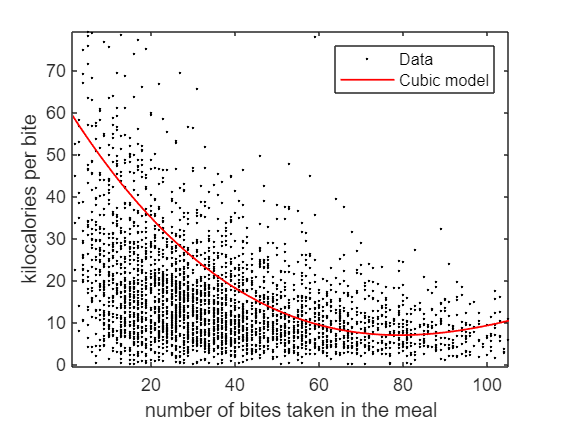

plot(num_bites_in_meal, kcal_per_bite, '.black', 'MarkerSize',4);
xlim([1.4 105.1])
ylim([-0.4 79.2])
hold on;
plot(x,y, Color='red', LineWidth=1);
legend('Data', 'Cubic model', 'Location','northeast');
% title('Fitting a cubic model');
xlabel('number of bites taken in the meal');
ylabel('kilocalories per bite');
hold off;


% Evaluating the model fit by calculating the residual squared
residual = sum(num_bites_in_meal) - sum(a1*power(kcal_per_bite,3) + a2*power(kcal_per_bite,2) + a3*kcal_per_bite + a4);
residualsquared_cubic = residual^2

residualsquared_cubic = 8.4703e-20

Model-4: Fitting a non-linear exponential fucntion with equation `y = a1*e^-x`

% Number of given data points is 3398
N = 3398;

% Number of basis function is 1
M = 1;

% Matrix A of order N X M
A = [exp(-kcal_per_bite)];

% Matrix B of order N x 1
B = num_bites_in_meal;

% Solving the linear unknowns
X = inv(transpose(A)*A)*transpose(A)*B;

% Linear unkowns
a1 = X

a1 = 130.3513

y = a1*(exp(-20))

y = 2.6867e-07

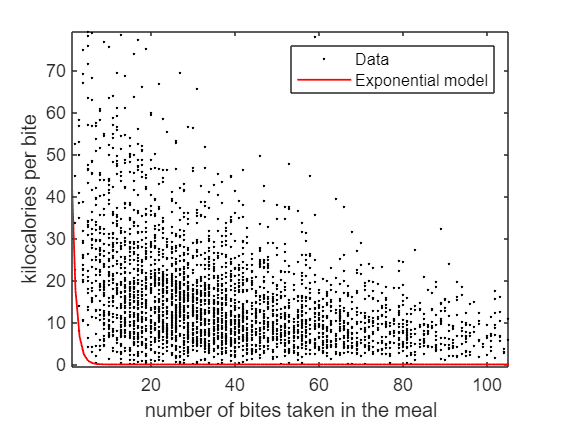

% Plotting the 2-D line model and the data point
x = 0:1:200;
y = a1*exp(-x);
plot(num_bites_in_meal, kcal_per_bite, '.black', 'MarkerSize',4);
xlim([1.4 105.1])
ylim([-0.4 79.2])
hold on;
plot(x,y, Color='red', LineWidth=1);
legend('Data', 'Exponential model', 'Location','northeast');
% title('Fitting an exponential model');
xlabel('number of bites taken in the meal');
ylabel('kilocalories per bite');
hold off;


% Evaluating the model fit by calculating the residual squared
residual = sum(num_bites_in_meal) - sum(a1*exp(-kcal_per_bite));
residualsquared_exp = residual^2

residualsquared_exp = 1.8242e+10

**Evaluating all the models based on their residual squared value. **

% Finding the model with the least residual value out of the four models
residual_values = [residualsquared_quad, residualsquared_ratqaud, residualsquared_cubic, residualsquared_exp];
min(residual_values)

ans = 7.6233e-21

Out of all the above models, it can be seen that the quadratic (y = 0.0047*x^2 - 1.1417*x + 57.6343) model best represent the nature of the data, since it has the least squared residual value. 

y = -0.00003*20^3 + 0.014*20^2 -1.58*20+ 61.22

y = 34.9800